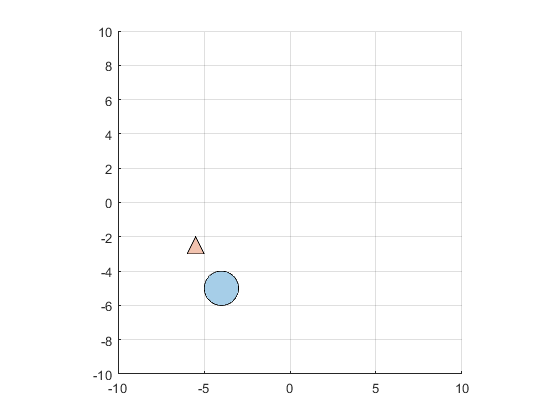

close all
c = circle;
p1 = polyshape(circle.xdata,circle.ydata);
p2 = polyshape(triangle.xdata,triangle.ydata);
x = [1 0];
y = [0 1];
trans = zeros(3,2);
[v1,b1,v2,b2] = generateRandomV(2);
for i = linspace(0,3,50)
    v =   ac*i;
    vb = acb*i;
    f = translate(p1, v1+b1);
    f2 = translate(p2,v2+b2);
    % agregar velocidad y un punto de inicio aleatorio
    % detectar colisiones para poligonos
    for j =1:3
        trans(j,:) = [dot(x,f2.Vertices(j,:)), dot(y,f2.Vertices(j,:))];
    end
    p1min = min(trans);
    p1max = max(trans);
    if p1min(1,1) < -10 || p1max(1,1) > 10
        title('Collision with x axis triangle')
        break
    elseif p1min(1,2) < -10 || p1max(1,2) > 10
        title('Colision with y axis triangle')
        break
    end
    [cx,cy] = centroid(f);
    if cx+c.r >= 10 || cx-c.r <= -10
        title('Colision with x axis circle')
        break
    elseif cy+c.r > 10 || cy-c.r <-10
        title('Colision with y axis circle')
        break
    end
    renderer([f,f2])
end

np = 3;
nrand = randi([-10,10],np*4,1);
bs = 2;
n = numel(nrand);
res = mat2cell(nrand,diff([0:bs:n-1,n]))

res = 6×1 cell array
    {2×1 double}
    {2×1 double}
    {2×1 double}
    {2×1 double}
    {2×1 double}
    {2×1 double}


res{1}

ans =      6
    -7


[v1,b1,v2,b2,v3,b3]=generateRandomV(3)

v1 =      6
    -2


b1 =      6
     5


v2 =     -3
    -6


b2 =      6
     9


v3 =     -4
     4


b3 =     -1
     7
